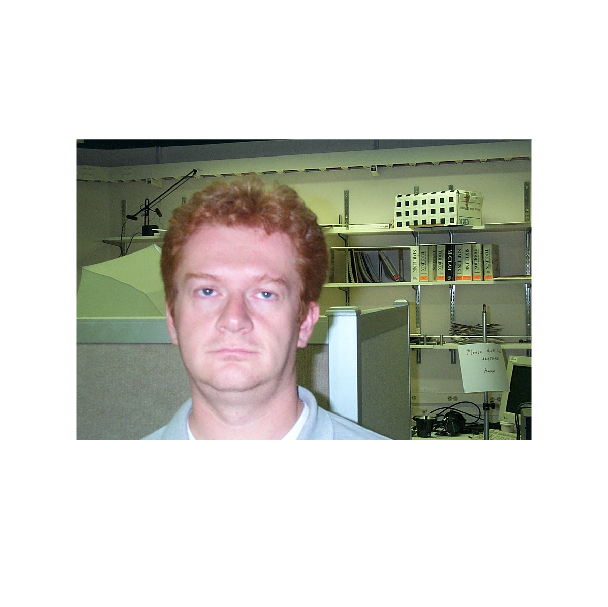

clear
realId = 2; 

% Se till att du är i "/GitHub/TNM034_Projekt" när du läser in 
%image = imread("./Faces/db1_" + realId + ".jpg");
%image = imread("./Faces/db0_" + realId + ".jpg");
%image = imread("./Faces/DB2/il_" + realId + ".jpg");
%image = imread("./Faces/DB2/cl_" + realId + ".jpg");
%image = imread("./Faces/DB2/ex_" + realId + ".jpg");
image = imread("./Faces/DB2/bl_" + realId + ".jpg");

image = im2double(image);
imshow(image)

id = tnm034(image)

Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.

From getFaceId:

Distance id 1: 8.243e-02
Distance id 2: 1.097e-01
Distance id 3: 1.033e-01
Distance id 4: 1.620e-01
Distance id 5: 1.520e-01
Distance id 6: 1.493e-01
Distance id 7: 7.128e-02
Distance id 8: 2.086e-01
Distance id 9: 1.389e-01
Distance id 10: 9.935e-02
Distance id 11: 7.336e-02
Distance id 12: 6.193e-02
Distance id 13: 1.015e-01
Distance id 14: 1.070e-01
Distance id 15: 1.177e-01
Distance id 16: 8.913e-02

Closest id: 12


id = 12


if id == realId
    fprintf('Correct id!')
else
    fprintf('Not correct id :/')
end   

Not correct id :/

## Tetst All Images

%clear all
% Load face images from a folder
imageDir = 'Faces/';
imageDir2 = 'Faces/DB2/';
testimages = dir(fullfile(imageDir, '*.jpg'));
testimages2 = dir(fullfile(imageDir2, '*.jpg'));
allImages = [testimages; testimages2];
numImages = numel(allImages);

% Read images into a cell array
faceData = cell(1, numImages);
classIds = zeros(1, numImages);
for i = 1:numImages
    % Load your image
    image = im2double(imread(fullfile(allImages(i).folder, allImages(i).name)));
    %imshow(image)
    id = tnm034(image)
    fprintf('Image: %s',allImages(i).name);
    disp('===')
    pause(0.1)
end


From getFaceId:

min dist: 6935.943

Closest id: 5; 

id = 0

Image: db0_1.jpg

===



From getFaceId:

min dist: 8721.323

Closest id: 1; 

id = 0

Image: db0_2.jpg

===



From getFaceId:

min dist: 8019.622

Closest id: 14; 

id = 0

Image: db0_3.jpg

===



From getFaceId:

min dist: 9610.180

Closest id: 1; 

id = 0

Image: db0_4.jpg

===



From getFaceId:

min dist: 4920.325

Closest id: 1; 

id = 0

Image: db1_1.jpg

===



From getFaceId:

min dist: 4920.325

Closest id: 10; 

id = 0

Image: db1_10.jpg

===



From getFaceId:

min dist: 4920.325

Closest id: 11; 

id = 0

Image: db1_11.jpg

===



From getFaceId:

min dist: 4920.325

Closest id: 12; 

id = 0

Image: db1_12.jpg

===



From getFaceId:

min dist: 4920.325

Closest id: 13; 

id = 0

Image: db1_13.jpg

===



From getFaceId:

min dist: 4920.325

Closest id: 14; 

id = 0

Image: db1_14.jpg

===



From getFaceId:

min dist: 4920.325

Closest id: 15; 

id = 0

Image: db1_15.jpg

===



From getFaceId:

min dist: 4920.325

Closest id: 16; 

id = 0

Image: db1_16.jpg

===



From getFaceId:

min dist: 4920.325

Closest id: 2; 

id = 0

Image: db1_2.jpg

===



From getFaceId:

min dist: 4920.325

Closest id: 3; 

id = 0

Image: db1_3.jpg

===



From getFaceId:

min dist: 4920.325

Closest id: 4; 

id = 0

Image: db1_4.jpg

===



From getFaceId:

min dist: 4920.325

Closest id: 5; 

id = 0

Image: db1_5.jpg

===



From getFaceId:

min dist: 4920.325

Closest id: 6; 

id = 0

Image: db1_6.jpg

===
